clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = ".png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "./tex/images/";
% addpath("../CVX-arm64/");
% cvx_setup;
mkdir(SAVE_DIR);

T_task3 = 0.5;
a = 1.8;
b = 7.7;
zeta = 0.69;
omega_d = 5;
K_nu = 0.1;

## Task 1

T1 = 1;
G = tf([1], [b, 1], 'InputDelay', a)

G =
 
                    1
  exp(-1.8*s) * ---------
                7.7 s + 1
 
Continuous-time transfer function.
Model Properties


HGtf = c2d(G, T1, 'zoh')

HGtf =
 
           0.02564 z + 0.09615
  z^(-2) * -------------------
               z - 0.8782
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


HGss = ss(HGtf)

HGss =
 
  A = 
           x1
   x1  0.8782
 
  B = 
         u1
   x1  0.25
 
  C = 
           x1
   y1  0.4747
 
  D = 
            u1
   y1  0.02564
 
  Input delays (sampling periods): 2 
 
Sample time: 1 seconds
Discrete-time state-space model.


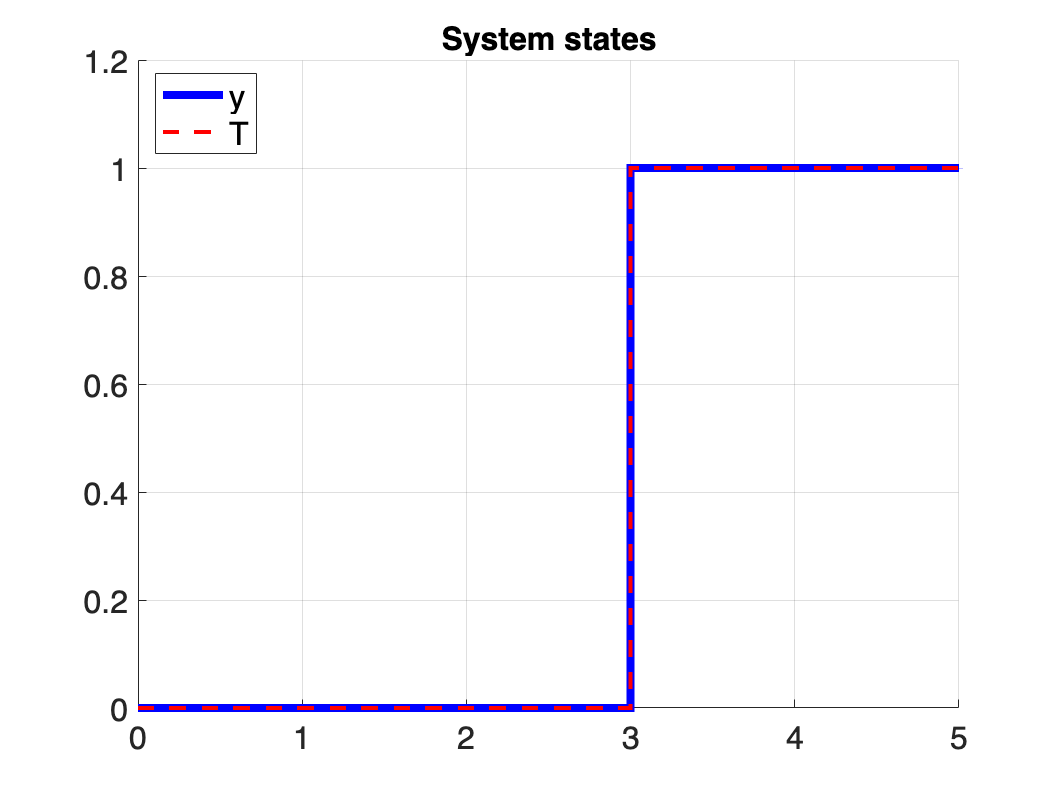

D1_disc = ss(tf([1.00000000000000 -0.878200000000000 0.0 0.0'], [0.0256400000000000 0.0961500000000000 0.0 -0.0256400000000000 -0.0961500000000000], 1));
D1_disk_min = minreal(D1_disc);

sim_res = sim("task1_3.slx", 5);
clf;
title("System states");
hold on;
stairs(sim_res.y.time, sim_res.y.data, 'LineWidth', 4, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.T.time, sim_res.T.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--');
grid on;
legend({'y', 'T'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task1_3" + SAVE_EXT);

pole(c2d(tf([1 -0.8782 0 0], [0.02564 0.09165 0 -0.02564 -0.09615]), T1, 'zoh'))

ans =    2.7527 + 0.0000i
   0.3831 + 0.4667i
   0.3831 - 0.4667i
   0.0279 + 0.0000i


## **Task 2**

T_disc = 1; % Sampling time

% Define the continuous-time plant G(s) without delay
G_no_delay = tf([1], [b, 1]);

% Discretize G(s) without delay
Gd_no_delay = c2d(G_no_delay, T_disc, 'zoh');

% Compute the integer number of delay steps
Delay_steps = round(a / T_disc);

% Create the delay in z-domain
Delay_z = tf([zeros(1, Delay_steps) 1], 1, T_disc);

% Total discrete plant Gd(z) = Gd_no_delay(z) * Delay_z
Gd = series(Gd_no_delay, Delay_z);

% Specify the desired closed-loop time constant (Tau_c)
Tau_c = 5; % Desired time constant (specify the value)

% Compute the exponential term used in the desired closed-loop transfer function
e_Tc = exp(-T_disc / Tau_c);

% Define the desired closed-loop transfer function H_d(z)
H_d = tf([1 - e_Tc], [1, -e_Tc], T_disc);

% Compute the Dahlin controller C(z)
% Handle the delay separately to avoid division errors
C = ((H_d / (1 - H_d)) / Gd_no_delay) * Delay_z;

% Simplify the controller to its minimal realization
C = minreal(C);

% Display the Dahlin controller
disp('The Dahlin controller C(z) is:');

The Dahlin controller C(z) is:


C

C =
 
  1.488 z - 1.307
  ---------------
       z - 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Gd_no_delay

Gd_no_delay =
 
    0.1218
  ----------
  z - 0.8782
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties
